## Setup and Variables


clear
close all
% data = readtable('./Run_30Khz_BW_test1_prf3k/1_AvgData.csv')  % Read the CSV file into a table
data = readtable('./Run_30Khz_BW_test1_prf3k/0_RunData.csv')  % Read the CSV file into a table

data = 24000×30 table
    Var1    RNTI    numDLTotal    numDLnew    numReTx_DL    avgMCS_DL    numULTotal    numULnew    numReTx_UL    avgMCS_UL    DL_throughput_bits    DL_goodput_bits    UL_throughput_bits    UL_goodput_bits    TTI    PulseBWoffset    numRBs    NumFrames    pulseAttenuation                FolderName                 prf     FreqOffset    PulseWidth       BW       DL_throughput_bps    DL_goodput_bps    UL_throughput_bps    UL_goodput_bps    DLReTxPrcnt    ULReTxPrcnt
 


% data = data(data.BW == 5000000,:)
% data = data(mod(data.prf, 5) == 0, :);
% Filter data for different TTI values
tti2 = data(data.TTI == 2, :);
tti4 = data(data.TTI == 4, :);
tti7 = data(data.TTI == 7, :);
tti14 = data(data.TTI == 14, :);

% Define colors
color1 = [1, 0.3, 0];   % Bright orange
color2 = [0, 0.5, 0.8]; % Cool blue
color3 = [0.2, 0.7, 0.2]; % Vibrant green
color4 = [0.5, 0.2, 0.7]; % Optional color for TTI 14
% Define a blending factor for lighter colors (closer to white)
blend_factor = 0.6;

% Create lighter versions of the colors
color5 = color1 + blend_factor * ([1, 1, 1] - color1); % Lighter orange
color6 = color2 + blend_factor * ([1, 1, 1] - color2); % Lighter blue
color7 = color3 + blend_factor * ([1, 1, 1] - color3); % Lighter green
color8 = color4 + blend_factor * ([1, 1, 1] - color4); % Lighter purple
alpha_level = 0.5;


% Create figure
xvar = 'BW';
yvar = 'DL_goodput_bps';
% yvar2 = 'DL_throughput_bps';
figure;
gcf;
hold on;
grid on;
title('Avg Goodput Per UE against varying BWs');
xlabel('BW');
ylabel('Avg Goodput per UE (Mbps)');
% 
% Plot scatter points with specific colors
xscale = 1;
yscale = 1e-3;
tti2.(xvar) = tti2.(xvar)* xscale;tti2.(yvar) = tti2.(yvar)* yscale;
% tti2.(yvar2) = tti2.(yvar2)* yscale;
tti4.(xvar) = tti4.(xvar)* xscale;tti4.(yvar) = tti4.(yvar)* yscale;
% tti4.(yvar2) = tti4.(yvar2)* yscale;
tti7.(xvar) = tti7.(xvar)* xscale;tti7.(yvar) = tti7.(yvar)* yscale;
% tti7.(yvar2) = tti7.(yvar2)* yscale;
tti14.(xvar) = tti14.(xvar)* xscale;tti14.(yvar) = tti14.(yvar)* yscale;
% tti14.(yvar2) = tti14.(yvar2)* yscale;

tti2_plot = scatter((tti2.(xvar)), (tti2.(yvar)), 50, 'filled', 'DisplayName', 'TTI 2 GP', 'MarkerFaceColor', color1,'MarkerFaceAlpha', alpha_level);
tti4_plot = scatter((tti4.(xvar)), (tti4.(yvar)), 50, 'filled', 'DisplayName', 'TTI 4 GP', 'MarkerFaceColor', color2,'MarkerFaceAlpha', alpha_level);
tti7_plot = scatter((tti7.(xvar)), (tti7.(yvar)), 50, 'filled', 'DisplayName', 'TTI 7 GP', 'MarkerFaceColor', color3,'MarkerFaceAlpha', alpha_level);
tti14_plot = scatter((tti14.(xvar)), (tti14.(yvar)), 50, 'filled', 'DisplayName', 'TTI 14 GP', 'MarkerFaceColor', color4,'MarkerFaceAlpha', alpha_level);

% tti2_plot = scatter((tti2.(xvar)), (tti2.(yvar2)), 50, 'filled', 'DisplayName', 'TTI 2 TP', 'MarkerFaceColor', color5,'MarkerFaceAlpha', alpha_level);
% tti4_plot = scatter((tti4.(xvar)), (tti4.(yvar2)), 50, 'filled', 'DisplayName', 'TTI 4 TP', 'MarkerFaceColor', color6,'MarkerFaceAlpha', alpha_level);
% tti7_plot = scatter((tti7.(xvar)), (tti7.(yvar2)), 50, 'filled', 'DisplayName', 'TTI 7 TP', 'MarkerFaceColor', color7,'MarkerFaceAlpha', alpha_level);
% tti14_plot = scatter((tti14.(xvar)), (tti14.(yvar2)), 50, 'filled', 'DisplayName', 'TTI 14 TP', 'MarkerFaceColor', color8,'MarkerFaceAlpha', alpha_level);

tti2DLMax = yline(496696.0 * yscale,'--','LabelHorizontalAlignment','right', 'Color',color1);
tti4DLMax = yline(2081720.0* yscale,'--','TTI 4 DL Max','LabelHorizontalAlignment','right', 'Color',color2);
tti7DLMax = yline(3430896.0* yscale,'--','TTI 7 DL Max','LabelHorizontalAlignment','right', 'Color',color3);
tti14DLMax = yline(3785808.0* yscale,'--','TTI 14 DL Max','LabelHorizontalAlignment','right', 'Color',color4);


% Add trendlines for TTI = 2, 4, and 7
% Trendline for TTI = 2
trendlineNumeral = 3;
[x_fit2, y_fit2] = setupTrendlines(tti2, trendlineNumeral,xvar,yvar);

[x_fit4, y_fit4] = setupTrendlines(tti4, trendlineNumeral,xvar,yvar);

[x_fit7, y_fit7] = setupTrendlines(tti7, trendlineNumeral,xvar,yvar);

[x_fit14, y_fit14] = setupTrendlines(tti14, trendlineNumeral,xvar,yvar);

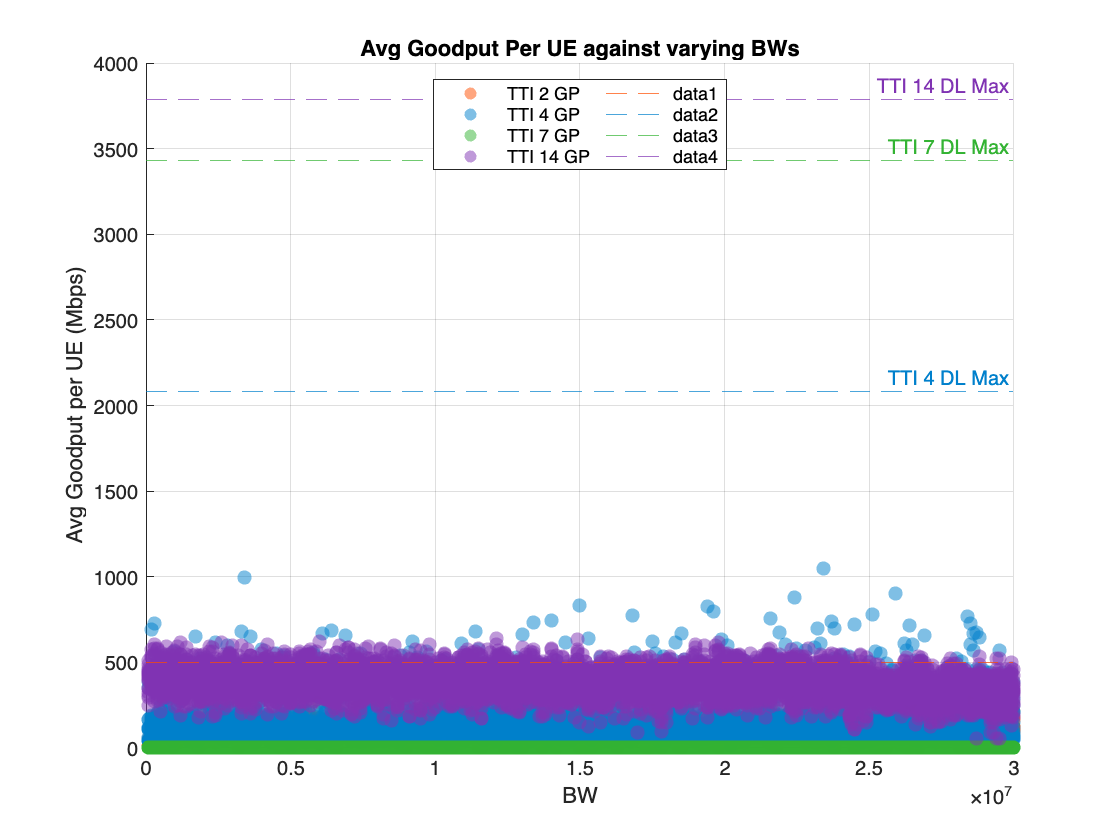

% TTI2_trend = plot(x_fit2, y_fit2, '-', 'Color', color1, 'LineWidth', 2, 'DisplayName', 'TTI 2 GP');
% TTI4_trend =plot(x_fit4, y_fit4, '-', 'Color', color2, 'LineWidth', 2, 'DisplayName', 'TTI 4 GP');
% TTI7_trend =plot(x_fit7, y_fit7, '-', 'Color', color3, 'LineWidth', 2, 'DisplayName', 'TTI 7 GP');
% TTI14_trend =plot(x_fit14, y_fit14, '-', 'Color', color4, 'LineWidth', 2, 'DisplayName', 'TTI 14 GP');



% [x_fit2, y_fit2] = setupTrendlines(tti2, trendlineNumeral,xvar,yvar2);
% [x_fit4, y_fit4] = setupTrendlines(tti4, trendlineNumeral,xvar,yvar2);
% [x_fit7, y_fit7] = setupTrendlines(tti7, trendlineNumeral,xvar,yvar2);
% [x_fit14, y_fit14] = setupTrendlines(tti14, trendlineNumeral,xvar,yvar2);
% TTI2_trend2 = plot(x_fit2, y_fit2, '-', 'Color', color5, 'LineWidth', 2, 'DisplayName', 'TTI 2 TP');
% TTI4_trend2 =plot(x_fit4, y_fit4, '-', 'Color', color6, 'LineWidth', 2, 'DisplayName', 'TTI 4 TP');
% TTI7_trend2 =plot(x_fit7, y_fit7, '-', 'Color', color7, 'LineWidth', 2, 'DisplayName', 'TTI 7 TP');
% TTI14_trend2 =plot(x_fit14, y_fit14, '-', 'Color', color8, 'LineWidth', 2, 'DisplayName', 'TTI 14 TP');

% Create legend
legend('Location', 'north','NumColumns', 2);

legend([TTI2_trend,TTI4_trend,TTI7_trend,TTI14_trend,TTI2_trend2,TTI4_trend2,TTI7_trend2,TTI14_trend2])

Unrecognized function or variable 'TTI2_trend'.

saveFolder = 'Images/Plots/' ;
save_name = strcat(saveFolder,xvar, '_vs_', yvar,'20MHzPulseBW_3');
% saveas(gcf, strcat(save_name, '.png'));  % Save as PNG
hold off;

PRF = 2000

% data = data(data.prf == 2000,:);
% tti2 = data(data.TTI == 2, :);
% tti4 = data(data.TTI == 4, :);
% tti7 = data(data.TTI == 7, :);
% tti14 = data(data.TTI == 14, :);

% Create figure
xvar = 'prf';
yvar = 'DL_goodput_bps';
figure;

hold on;
grid on;
title('');
xlabel(xvar,'Interpreter', 'none');
ylabel(yvar,'Interpreter', 'none');
xlim([1500 3000])
% Plot scatter points with specific colors
tti2_plot = scatter(tti2.(xvar), tti2.(yvar), 50, 'filled', 'DisplayName', 'TTI 2', 'MarkerFaceColor', color1,'MarkerFaceAlpha', alpha_level);
tti4_plot = scatter(tti4.(xvar), tti4.(yvar), 50, 'filled', 'DisplayName', 'TTI 4', 'MarkerFaceColor', color2,'MarkerFaceAlpha', alpha_level);
tti7_plot = scatter(tti7.(xvar), tti7.(yvar), 50, 'filled', 'DisplayName', 'TTI 7', 'MarkerFaceColor', color3,'MarkerFaceAlpha', alpha_level);
tti14_plot = scatter(tti14.(xvar), tti14.(yvar), 50, 'filled', 'DisplayName', 'TTI 14', 'MarkerFaceColor', color4,'MarkerFaceAlpha', alpha_level);

tti2DLMax = yline(496696.0,'--','DisplayName','TTI 2 DL Avg No Radar', 'Color',color1);
tti4DLMax = yline(2081720.0,'--','DisplayName','TTI 4 DL Avg No Radar', 'Color',color2);
tti7DLMax = yline(3430896.0,'--','DisplayName','TTI 7 DL Avg No Radar', 'Color',color3);
tti14DLMax = yline(3785808.0,'--','DisplayName','TTI 14 DL Avg No Radar', 'Color',color4);


% Add trendlines for TTI = 2, 4, and 7
% Trendline for TTI = 2
% [x_fit2, y_fit2] = setupTrendlines(tti2, 2,xvar,yvar);
% [x_fit4, y_fit4] = setupTrendlines(tti4, 2,xvar,yvar);
% [x_fit7, y_fit7] = setupTrendlines(tti7, 2,xvar,yvar);
% % [x_fit14, y_fit14] = setupTrendlines(tti14, 2,xvar,yvar);
% plot(x_fit2, y_fit2, '-', 'Color', color1, 'LineWidth', 2, 'DisplayName', 'TTI 2 Trendline');
% plot(x_fit4, y_fit4, '-', 'Color', color2, 'LineWidth', 2, 'DisplayName', 'TTI 4 Trendline');
% plot(x_fit7, y_fit7, '-', 'Color', color3, 'LineWidth', 2, 'DisplayName', 'TTI 7 Trendline');
% plot(x_fit14, y_fit14, '-', 'Color', color4, 'LineWidth', 2, 'DisplayName', 'TTI 14 Trendline');

% Create legend
legend('Location', 'northeast');
saveFolder = 'Images/Plots/' ;
save_name = strcat(saveFolder,xvar, '_vs_', yvar,'20MHzPulseBW_3_v2');
% saveas(gcf, strcat(save_name, '.png'));  % Save as PNG
hold off;

## Function Calls


% Call the function
% plotScatterWithTrendlines('avgMCS_DL', 'DL_throughput_bps', tti2, tti4, tti7,tti14, color1, color2, color3, color4,alpha_level);
% plotScatterWithTrendlines('avgMCS_DL', 'DL_goodput_bps', tti2, tti4, tti7,tti14, color1, color2, color3, color4,alpha_level);
% plotScatterWithTrendlines('DLReTxPrcnt','DL_goodput_bps', tti2, tti4, tti7,tti14, color1, color2, color3, color4,alpha_level);
% plotScatterWithTrendlines('prf','DLReTxPrcnt', tti2, tti4, tti7,tti14, color1, color2, color3, color4,alpha_level);
% plotScatterWithTrendlines('PulseWidth','DLReTxPrcnt', tti2, tti4, tti7,tti14, color1, color2, color3, color4,alpha_level);
% plotScatterWithTrendlines('BW','DL_goodput_bps', tti2, tti4, tti7,tti14, color1, color2, color3, color4,alpha_level);
% plotScatterWithTrendlines('FreqOffset','DL_goodput_bps',tti2, tti4, tti7,tti14, color1, color2, color3, color4,alpha_level);


function plotScatterWithTrendlines(xvar, yvar, tti2, tti4, tti7,tti14, color1, color2, color3, color4,alpha_level)
    % plotScatterWithTrendlines - Plots scatter points and trendlines for given x and y variables
    %
    % Syntax: plotScatterWithTrendlines(xvar, yvar, tti2, tti4, tti7, color1, color2, color3, alpha_level)
    %
    % Inputs:
    %   xvar       - String, name of the x-axis variable
    %   yvar       - String, name of the y-axis variable
    %   tti2       - Table, data for TTI 2
    %   tti4       - Table, data for TTI 4
    %   tti7       - Table, data for TTI 7
    %   color1     - Array, RGB color for TTI 2
    %   color2     - Array, RGB color for TTI 4
    %   color3     - Array, RGB color for TTI 7
    %   alpha_level - Double, transparency level for scatter points (0 to 1)
    %
    % Outputs:
    %   None (creates a plot and saves it to file)

    % Create figure
    figure;
    hold on;
    title('');
    xlabel(xvar, 'Interpreter', 'none');
    ylabel(yvar, 'Interpreter', 'none');

    % Plot scatter points with specific colors
    scatter(tti2.(xvar), tti2.(yvar), 50, 'filled', 'DisplayName', 'TTI 2', ...
        'MarkerFaceColor', color1, 'MarkerFaceAlpha', alpha_level);
    scatter(tti4.(xvar), tti4.(yvar), 50, 'filled', 'DisplayName', 'TTI 4', ...
        'MarkerFaceColor', color2, 'MarkerFaceAlpha', alpha_level);
    scatter(tti7.(xvar), tti7.(yvar), 50, 'filled', 'DisplayName', 'TTI 7', ...
        'MarkerFaceColor', color3, 'MarkerFaceAlpha', alpha_level);
    scatter(tti14.(xvar), tti14.(yvar), 50, 'filled', 'DisplayName', 'TTI 14', ...
        'MarkerFaceColor', color3, 'MarkerFaceAlpha', alpha_level);
    % Add trendlines for TTI = 2, 4, 7, and 14
    % Trendline for TTI = 2
    [x_fit2, y_fit2] = setupTrendlines(tti2, 2);
    plot(x_fit2, y_fit2, '-', 'Color', color1, 'LineWidth', 2, 'DisplayName', 'TTI 2 Trendline');

    % Trendline for TTI = 4
    [x_fit4, y_fit4] = setupTrendlines(tti4, 2);
    plot(x_fit4, y_fit4, '-', 'Color', color2, 'LineWidth', 2, 'DisplayName', 'TTI 4 Trendline');

    % Trendline for TTI = 7
    [x_fit7, y_fit7] = setupTrendlines(tti7, 2);
    plot(x_fit7, y_fit7, '-', 'Color', color3, 'LineWidth', 2, 'DisplayName', 'TTI 7 Trendline');
    
    % Trendline for TTI = 14 / Slot Based
    [x_fit14, y_fit14] = setupTrendlines(tti7, 2);
    plot(x_fit14, y_fit14, '-', 'Color', color3, 'LineWidth', 2, 'DisplayName', 'TTI 14 Trendline');

    % Create legend
    legend('Location', 'northwest');

    % Save the plot
    saveFolder = 'Images/Plots/' ;
    save_name = strcat(saveFolder,xvar, '_vs_', yvar);


    saveas(gcf, strcat(save_name, '.png'));  % Save as PNG
    hold off;
end

function [x_fit, y_fit] = setupTrendlines(tti,numfit,xvar,yvar)
    p = polyfit(tti.(xvar), tti.(yvar), numfit);
    x_fit = linspace(min(tti.(xvar)), max(tti.(xvar)), 100);
    y_fit = polyval(p, x_fit);
    % plot(x_fit2, y_fit2, '-', 'Color', color1, 'LineWidth', 2, 'DisplayName', 'TTI 2 Trendline');
end

function plotAll(xvar,yvar)
    figure;
    hold on;
    title('');
    xlabel(xvar,'Interpreter', 'none');
    ylabel(yvar,'Interpreter', 'none');
    
    % Plot scatter points with specific colors
    tti2_plot = scatter(tti2.(xvar), tti2.(yvar), 50, 'filled', 'DisplayName', 'TTI 2', 'MarkerFaceColor', color1,'MarkerFaceAlpha', alpha_level);
    tti4_plot = scatter(tti4.(xvar), tti4.(yvar), 50, 'filled', 'DisplayName', 'TTI 4', 'MarkerFaceColor', color2,'MarkerFaceAlpha', alpha_level);
    tti7_plot = scatter(tti7.(xvar), tti7.(yvar), 50, 'filled', 'DisplayName', 'TTI 7', 'MarkerFaceColor', color3,'MarkerFaceAlpha', alpha_level);
    tti14_plot = scatter(tti14.(xvar), tti14.(yvar), 50, 'filled', 'DisplayName', 'TTI 14', 'MarkerFaceColor', color4,'MarkerFaceAlpha', alpha_level);
    
    % Add trendlines for TTI = 2, 4, and 7
    % Trendline for TTI = 2
    [x_fit2, y_fit2] = setupTrendlines(tti2, 2,xvar,yvar);
    [x_fit4, y_fit4] = setupTrendlines(tti4, 2,xvar,yvar);
    [x_fit7, y_fit7] = setupTrendlines(tti7, 2,xvar,yvar);
    [x_fit14, y_fit14] = setupTrendlines(tti14, 2,xvar,yvar);
    
    plot(x_fit2, y_fit2, '-', 'Color', color1, 'LineWidth', 2, 'DisplayName', 'TTI 2 Trendline');
    plot(x_fit4, y_fit4, '-', 'Color', color2, 'LineWidth', 2, 'DisplayName', 'TTI 4 Trendline');
    plot(x_fit7, y_fit7, '-', 'Color', color3, 'LineWidth', 2, 'DisplayName', 'TTI 7 Trendline');
    plot(x_fit14, y_fit14, '-', 'Color', color4, 'LineWidth', 2, 'DisplayName', 'TTI 14 Trendline');
    
    % Create legend
    legend('Location', 'northeast');
    
    hold off;
end